Fie $f: I -> \mathbb{R}$ o functie derivabila de n ori intr-un punct $a \in I$. Polinomul Taylor de grad n al functiei f atasat in punctul a este:


$$(T_nf)(x) = f(a) + \frac{x-a}{1!}*f'(a) + \frac{(x-a)^2}{2!}*f''(a) + .. + \frac{(x-a)^n}{n!}*f^{(n)}(a)$$


Restul (eroarea) in forma Lagrange al seriei este:


$$(R_nf)(x) = \frac{(x-a)^{n+1}*f^{(n+1)}(a+\theta*(x-a))}{(n+1)!}, 0 < \theta < 1$$


Seria Maclaurin reprezinta polinomul Taylor de grad n atasat in punctul 0, si este:


$$(T_nf)(x) = f(0) + \frac{x}{1!}*f'(0) + \frac{x^2}{2!}*f''(0) + ... + \frac{x^n}{n!}*f^{(n)}(0)$$


Iar restul (eroarea) este:


$$(R_nf)(x) = \frac{x^{n+1}*f^{(n+1)}(\theta*x)}{(n+1)!}, 0 < \theta < 1$$


Presupunand ca $\theta$ tinde spre 1, putem lua restul cu o margine superioara:


$$(R_nf)(x) = \frac{x^{n+1}*f^{(n+1)}(x)}{(n+1)!}$$


PROBLEME


$$f: \mathbb{R} \rightarrow \mathbb{R}, f(x) = \sqrt{a + x}, a > 0$$



$$f(x) = \sqrt{a} * (1 + \frac{x}{a})^\frac{1}{2}$$


% Maclaurin Series
syms f a x xi N exponent
assume(a > 0);

% 1/2
exponent = sym(1) / sym(2);

% our function
f = a^exponent * (1 + x / a)^exponent;

% N = degree of expansion
N = 5;

% the Maclaurin series -> Taylor series centered in the origin
% the expansion is made up to the (N - 1)th term (for N = 5 -> x^4)
Tnf1 = taylor(f, x, 0, "order", N);

% the rest of the Taylor expansion
Rnf1 = subs(diff(f, x, N), x, xi)*x^(N+1)/factorial(N+1);

disp(Tnf1);

$$\frac{x}{2\,\sqrt{a}}+\sqrt{a}-\frac{x^{2}}{8\,a^{3/2}}+\frac{x^{3}}{16\,a^{5/2}}-\frac{5\,x^{4}}{128\,a^{7/2}}$$

disp(Rnf1);

$$\frac{7\,x^{6}}{1536\,a^{9/2}\,{\left(\frac{\xi }{a}+1\right)}^{9/2}}$$


$$f: \mathbb{R} \rightarrow \mathbb{R}, f(x) = e^x * Tnf; n = ?, a= 0$$


Sa se aproximeze f in [-1, 1] cu TREI ZECIMALE EXACTE


$$Rnf = \frac{x^{n + 1} * e^{\theta*x}}{(n + 1)!}$$


$|Rnf| < 10^{-3}$; $\theta * x < 1 \land e^{\theta * x} < e < 3$


$$\Rightarrow Rnf < \frac{3}{(n + 1)!} < 10^{-3}$$


syms n rest(n)

rest(n) = 3 / factorial(n + 1);

% adjust for determining the minimum n so that
% the f function approximates the result with that exact number of decimals
num_decimals = 3;

for k=3:100
    % compute rest(k) with variable-precision arithmetic
    r = vpa(rest(k));
    disp([k,r]);

    % stop if the remainder if we reached the desired number of decimals
    if abs(double(r)) < 10^(-num_decimals)
        break;
    end
end

$$\left(\begin{array}{cc} 3 & 0.125 \end{array}\right)$$

$$\left(\begin{array}{cc} 4 & 0.025 \end{array}\right)$$

$$\left(\begin{array}{cc} 5 & 0.0041666666666666666666666666666667 \end{array}\right)$$

$$\left(\begin{array}{cc} 6 & 0.0005952380952380952380952380952381 \end{array}\right)$$


Tnf2 = taylor(exp(x), x, 0, 'order', k + 1);

disp(Tnf2);

$$\frac{x^{6}}{720}+\frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$


% subs x with 1.0
% variable-precision arithmetic with 10 decimals
disp(vpa(subs(Tnf2, x, 1.0), 30));

$$2.71805555555555555555555555556$$

disp(vpa(exp(1), 30));

$$2.71828182845904553488480814849$$

$\sqrt[3]{999}$  aproximat cu 12 zecimale exacte


$$\sqrt[3]{999} = \sqrt[3]{1000 -1} = \sqrt[3]{1000 * (1 - \frac{1}{1000})} = -10 * (1 + \frac{1}{1000})^{\frac{1}{3}}$$



$$(1 + x)^{k} = 1 + {k \choose 1} * x + {k \choose 2} * x^2 + ... + {k \choose n} * x^n + Rn(x)$$


% changing the calculus precision
digits(13);

syms f(x) exponent R(n)

exponent = sym(1) / sym(3);
f_ln2(x) = 10 * (1 - x)^exponent;

% nchoosek(n, k) = nCk;
R(n) = vpa(nchoosek(exponent, n) * 10^(-3*n));

% searching for our value
for k=1:100
    r = vpa(R(k));
    disp([k,r]);

    if abs(double(r)) < 1e-12, break; end
end

$$\left(\begin{array}{cc} 1 & 0.0003333333333333 \end{array}\right)$$

$$\left(\begin{array}{cc} 2 & -0.0000001111111111111 \end{array}\right)$$

$$\left(\begin{array}{cc} 3 & 0.00000000006172839506173 \end{array}\right)$$

$$\left(\begin{array}{cc} 4 & -4.115226337449e-14 \end{array}\right)$$


% looks like 4 is enough
Tnf3 = taylor(f_ln2, x, 0, 'order', k + 1);
disp(Tnf3);

$$-\frac{100\,x^{4}}{243}-\frac{50\,x^{3}}{81}-\frac{10\,x^{2}}{9}-\frac{10\,x}{3}+10$$


% chaning back to default precision 32
digits(32);

% computing the result
disp(vpa(subs(Tnf3, x, 1e-3), 13));

$$9.996665554938$$


% same result, computed without any numerical method
disp(vpa(999^exponent, 13));

$$9.996665554938$$


$$erf(x) = \frac{2}{\sqrt{\pi}} \int_{0}^{x} e^-t^2 dt$$



$$d/dx \int_{0}^{x} f(t) dt = f(x)$$



$$e^x = 1 + x + x^2/2! + x^3/3! + ...$$



$$e^-t^2 = 1 - t^2 + t^4/2! - t^6/3! + ...$$



$$erf(x) = \frac{2}{\sqrt{\pi}} \int_{0}^{x} 1 - t^2 + t^4/2! - t^6/3! + ... \, dt$$



$$erf(x) = \frac{2}{\sqrt{\pi}} * \left[t- \frac{t^3}{3} + \frac{t^5}{5*2!} + ...\right]_0^x$$



$$erf(x) = \frac{2}{\sqrt{\pi}} * \left[x - \frac{x^3}{3} + \frac{x^5}{5*2!} + ... \right]$$



$$erf(x) = \frac{2}{\sqrt{\pi}}\sum_{n=0}^{\infty} \left[(-1)^n * \frac{x^{2n+1}}{(2n + 1) * n!} \right]$$


approx = my_erf(1, 20);
disp(vpa(approx, 10));

$$0.8427007929$$

disp(vpa(erf(1), 10));

$$0.8427007929$$


syms x;
Tnf4 = taylor(erf(x), x, 0, 'order', 5);
disp(Tnf4);

$$\frac{2\,x}{\sqrt{\pi }}-\frac{2\,x^{3}}{3\,\sqrt{\pi }}$$

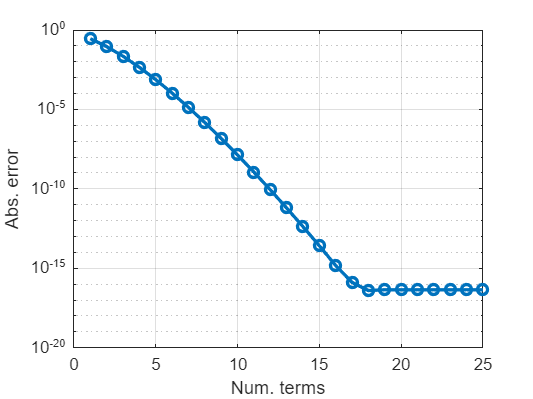


% plotting convergence for 'my_erf'
num_terms = 1:25;
x_val = 1;
errors = zeros(size(num_terms));

for i = 1:length(num_terms)
    value = my_erf(x_val, num_terms(i));
    errors(i) = abs(value - erf(x_val));
end

figure;
semilogy(num_terms, errors, 'o-', 'LineWidth', 2);
grid on;
xlabel('Num. terms');
ylabel('Abs. error');

Serie Taylor pentru ln(1 + x) ?

ln(2) aprox. = ? folosind primi 8 termeni.

Cati termeni sunt necesari pentru ln(2) cu 5 zecimale corecte?

La fel si pt $\ln(\frac{1+x}{1-x})$


$$\ln(1+x) = x - \frac{x^2}{2} + \frac{x^3}{3} + (-1)^n * \frac{x^{n+1}}{n+1} + R_{n + 1}(x)$$



$$(R_{n+1}f)(x) = \frac{(x-a)^{n+2} * (\ln(1+x))^{(n+2)}*(a + \theta * (x - a))}{(n +2)!}, 0 < \theta < 1$$



$$\ln^{n}(1+x) = (-1)^{n-1}*\frac{(n-1)!}{(x+1)^n}, n \ge 1$$



$$\ln^{n+2}(1+x) = (-1)^{n + 1}*\frac{(n+1)!}{(x+1)^{n+2}}$$



$$(R_{n+1}f)(1) = \frac{(-1)^{n+1}*\frac{(n+1)!}{2^{n+2}}}{(n+2)!} = \frac{(-1)^{n+1}*(n+1)!}{2^{n+2}*(n+2)!}$$


syms f x xi Tnf5_gt(x, n) R1(n) R2(n)

num_terms = 8;
num_decimals = 5;

% ln(2)
f = log(1 + x);

% assuming a is 0 and not considering Theta
Tnf5_1 = taylor(f, x, 0, 'order', num_terms)

$$Tnf5\_1 = \frac{x^{7}}{7}-\frac{x^{6}}{6}+\frac{x^{5}}{5}-\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

Rnf5_1 = subs(diff(f, x, num_terms+ 2), x, xi) * x^(num_terms + 2) / factorial(n + 2)

$$Rnf5\_1 = -\frac{362880\,x^{10}}{\left(n+2\right)!\,{\left(\xi +1\right)}^{10}}$$


% ln(2) with first 8 terms
ln2 = subs(Tnf5_1, x, 1.0);

$$ln2 = \frac{319}{420}$$

disp(vpa(ln2));

$$0.75952380952380952380952380952381$$


% determining how many terms do we need to include so that ln2 is
% approximated with 5 correct decimals
R1(n) = vpa(((-1)^(n+1) * factorial(n+1)) / (2^(n+2) * factorial(n+2)));
Tnf5_gt(x, n) = ((-1)^(n + 1) * factorial(n+1) / 2^(n+2)) / (x+1)^(n+2);

for k=1:600
    % compute rest(k) with variable-precision arithmetic
    r = vpa(Tnf5_gt(1, k));

    if mod(k,50) == 0
        disp([k,r]);
    end

    % stop if the remainder if we reached the desired number of decimals
    if abs(double(r)) < 10^(-num_decimals)
        break;
    end
end

$$\left(\begin{array}{cc} 50 & -7.647605898897322917066836807897e+34 \end{array}\right)$$

$$\left(\begin{array}{cc} 100 & -3.6661135573621946544959058859161e+98 \end{array}\right)$$

$$\left(\begin{array}{cc} 150 & -2.6469861954025672135982368916821e+173 \end{array}\right)$$

$$\left(\begin{array}{cc} 200 & -3.8367760389286121234575785546925e+255 \end{array}\right)$$

$$\left(\begin{array}{cc} 250 & -1.5493241921900426826245910551422e+343 \end{array}\right)$$

$$\left(\begin{array}{cc} 300 & -1.3875612352804065410915913924257e+435 \end{array}\right)$$

$$\left(\begin{array}{cc} 350 & -5.1542370122449641303909830392797e+530 \end{array}\right)$$

$$\left(\begin{array}{cc} 400 & -2.4068112704284966620983896022725e+629 \end{array}\right)$$

$$\left(\begin{array}{cc} 450 & -5.7803138548941047332399742368255e+730 \end{array}\right)$$

$$\left(\begin{array}{cc} 500 & -3.5655835247252584242212602166281e+834 \end{array}\right)$$

$$\left(\begin{array}{cc} 550 & -3.242557170314505962950787145279e+940 \end{array}\right)$$

$$\left(\begin{array}{cc} 600 & -2.7608744575054498493075152280492e+1048 \end{array}\right)$$


Tnf5_k_1 = taylor(f, x, 0, 'order', k);
disp(Tnf5_k_1);


disp(vpa(subs(Tnf5_k_1, x, 1.0), 5));

$$0.69398$$


% ln((1+x)/(1-x))
f = log((1+x)/(1-x));

Tnf5_2 = taylor(f, x, 0, 'order', num_terms);
Rnf5_2 = subs(diff(f, x, num_terms+ 2), x, xi) * x^(num_terms + 2) / factorial(n + 2);

disp(Tnf5_2);

$$\frac{2\,x^{7}}{7}+\frac{2\,x^{5}}{5}+\frac{2\,x^{3}}{3}+2\,x$$

disp(Rnf5_2);


ln2 = subs(Tnf5_2, x, vpa(1/3));
disp(vpa(ln2));

$$0.69313475733228819648572734992488$$


disp(vpa(log(2))); % actual ln(2)

$$0.69314718055994528622676398299518$$

Seria Taylor pentru arctg(x)?

Cati termeni sunt necesari pt a obtine $\frac{\pi}{4}$ cu 5 zecimale corecte?


$$\arctan(x) = x - \frac{x^3}{3} + \frac{x^5}{5} - ... = \sum_{k=0}^{\infty}{\frac{(-1)^k*x^{2k+1}}{2k+1}$$



$$\arctan'(x) = \frac{1}{x^2+1}$$



$$\arctan''(x) = -\frac{2x}{(x^2+1)^2}$$



$$\arctan'''(x) = -\frac{2*(x^2+1)^2 - ((x^2+1)^2)'*2x}{(x^2+1)^4} = -\frac{2(x^2+1)^2-[2*(x^2+1)*2x]*2x}{(x^2+1)^4} = -\frac{2(x^2+1)^2-8x^2*(x^2+1)}{(x^2+1)^4} = -2 * \frac{1-3x^2}{(x^2+1)^3}$$



$$\arctan^{(4)}(x) = 2 * \frac{(3x^2-1)' * (x^2+1)^3 - (3x^2-1)*((x^2+1)^3)'}{(x^2+1)^6} = 2 * \frac{6x*(x^2+1)^3 - 6x*(3x^2-1)*(x^2+1)^2}{(x^2+1)^6} = 2*\frac{6x*(x^2+1)^2*[x^2+1 - 3x^2 + 1]}{(x^2+1)^6} = 24x*\frac{1-x^2}{(x^2+1)^4}$$



$$\arctan^{(n)}(x) = (-1)^{n-1} * \frac{(n-1)!}{(1+x^2)^\frac{n}{2}} * \sin(n * \arcsin(\frac{1}{\sqrt{1+x^2}})), n \ge 1$$



$$(R_nf)(1) = \frac{(-1)^n*\frac{n!}{\sqrt{2^{n+1}}}*\sin((n+1)*\frac{pi}{4})}{(n+1)!} = \frac{(-1)^n*\sin((n+1)*\frac{pi}{4})}{\sqrt{2^{n+1}*(n+1)}$$



$$\frac{\pi}{4} = \arctan(1) = 1 - \frac{1}{3} + \frac{1}{5} - \frac{1}{7} + ...$$


syms arctan x R(n)

num_decimals = 5;

% arctan(x)
arctan = atan(x);

Tnf6 = taylor(arctan, x, 0, 'order', 10);
disp(Tnf6);

$$\frac{x^{9}}{9}-\frac{x^{7}}{7}+\frac{x^{5}}{5}-\frac{x^{3}}{3}+x$$


% R(n) = vpa(1/(2*n+1)); % -> aproximeaza bine
R(n) = (-1)^n * sin((n+1)*pi/4) / sqrt(2^(n+1)*(n+1))

$$R(n) = \frac{{\left(-1\right)}^{n}\,\sin\left(\frac{\pi \,\left(n+1\right)}{4}\right)}{\sqrt{2^{n+1}\,\left(n+1\right)}}$$


for k=1:100
    % skip k care fac ca sin((n+1)*pi/4)) = 0
    % pi * (n+1) / 4 = k*pi, k din Z
    % => n = 4k - 1 => n + 1 multiplu de 4
    if mod(k + 1, 4) == 0
        continue;
    end

    % compute rest(k) with variable-precision arithmetic
    r = vpa(R(k));
    disp([k,r]);

    % stop if the remainder if we reached the desired number of decimals
    if abs(double(r)) < 10^(-num_decimals)
        break;
    end
end

$$\left(\begin{array}{cc} 1 & -0.35355339059327376220042218105242 \end{array}\right)$$

$$\left(\begin{array}{cc} 2 & 0.14433756729740644112728719512549 \end{array}\right)$$

$$\left(\begin{array}{cc} 4 & -0.055901699437494742410229341718282 \end{array}\right)$$

$$\left(\begin{array}{cc} 5 & 0.051031036307982877045776751556373 \end{array}\right)$$

$$\left(\begin{array}{cc} 6 & -0.023622779563076701700907283514636 \end{array}\right)$$

$$\left(\begin{array}{cc} 8 & 0.010416666666666666666666666666667 \end{array}\right)$$

$$\left(\begin{array}{cc} 9 & -0.0098821176880261854124965423263522 \end{array}\right)$$

$$\left(\begin{array}{cc} 10 & 0.0047111147590275566038564385464072 \end{array}\right)$$

$$\left(\begin{array}{cc} 12 & -0.0021667976415048012578841473963164 \end{array}\right)$$

$$\left(\begin{array}{cc} 13 & 0.0020879784524408155053480740693731 \end{array}\right)$$

$$\left(\begin{array}{cc} 14 & -0.0010085894130748481471821003645267 \end{array}\right)$$

$$\left(\begin{array}{cc} 16 & 0.00047370239264908783890411418382055 \end{array}\right)$$

$$\left(\begin{array}{cc} 17 & -0.00046035597733499187786513304824534 \end{array}\right)$$

$$\left(\begin{array}{cc} 18 & 0.00022403880260797047451875935361121 \end{array}\right)$$

$$\left(\begin{array}{cc} 20 & -0.0001065517042167931549150866628006 \end{array}\right)$$

$$\left(\begin{array}{cc} 21 & 0.00010410191228301290737228404903996 \end{array}\right)$$

$$\left(\begin{array}{cc} 22 & -0.000050906839369403018231970088147107 \end{array}\right)$$

$$\left(\begin{array}{cc} 24 & 0.0000244140625 \end{array}\right)$$

$$\left(\begin{array}{cc} 25 & -0.000023939957902610355459492488492633 \end{array}\right)$$

$$\left(\begin{array}{cc} 26 & 0.000011746221296989456471947200124145 \end{array}\right)$$

$$\left(\begin{array}{cc} 28 & -0.0000056669719902664753157524482374945 \end{array}\right)$$


Tnf6_k = taylor(arctan, x, 0, 'order', 2*k+1);
disp(Tnf6_k);

$$-\frac{x^{55}}{55}+\frac{x^{53}}{53}-\frac{x^{51}}{51}+\frac{x^{49}}{49}-\frac{x^{47}}{47}+\frac{x^{45}}{45}-\frac{x^{43}}{43}+\frac{x^{41}}{41}-\frac{x^{39}}{39}+\frac{x^{37}}{37}-\frac{x^{35}}{35}+\frac{x^{33}}{33}-\frac{x^{31}}{31}+\frac{x^{29}}{29}-\frac{x^{27}}{27}+\frac{x^{25}}{25}-\frac{x^{23}}{23}+\frac{x^{21}}{21}-\frac{x^{19}}{19}+\frac{x^{17}}{17}-\frac{x^{15}}{15}+\frac{x^{13}}{13}-\frac{x^{11}}{11}+\frac{x^{9}}{9}-\frac{x^{7}}{7}+\frac{x^{5}}{5}-\frac{x^{3}}{3}+x$$


disp(vpa(subs(Tnf6_k, x, 1.0)));

$$0.77647243456798660683881323107636$$

disp(vpa(pi/4));

$$0.78539816339744830961566084581988$$

$f \in C^n[a,b]$ poate fi aproximata folosind o serie Maclaurin trunchiata:


$$f(x) \approx T_n(x) = \sum_{k=0}^{n}(c_k*x^k), c_k=\frac{f^{(k)}(0)}{k!}$$


syms x

min_n = 2;
max_n = 6;
colors = {'r', 'b', 'g', 'm', 'y'};

% a) f(x) = e^x
f = exp(x)

$$f = {\mathrm{e}}^{x}$$

exp_value_1 = double(subs(f, x, 1));

f_numeric = matlabFunction(f);

% functie anonima pentru a determina c_k pt oricare k
c_k = @(k) vpa(subs(diff(f, x, k), x, 0) / factorial(k));

figure;
hold on;

x_range = linspace(-5, 5, 100);
plot(x_range, f_numeric(x_range), 'k', 'LineWidth', 2);

for n = min_n:max_n
    Tn = 0;
    for k = 0:n
        Tn = Tn + c_k(k) * x^k;
    end

    Tn_numeric = matlabFunction(Tn);
    approx_value = double(subs(Tn, x, 1));
    error_value = abs(approx_value - exp_value_1);

    fprintf("T_%d(1) = %e vs f(1) = %e | Error = %e\n", n, approx_value, exp_value_1, error_value);
    plot(x_range, Tn_numeric(x_range), colors{n-1}, 'LineWidth', 1.5, 'DisplayName', sprintf('T_%d(x)', n));
end

T_2(1) = 2.500000e+00 vs f(1) = 2.718282e+00 | Error = 2.182818e-01
T_3(1) = 2.666667e+00 vs f(1) = 2.718282e+00 | Error = 5.161516e-02
T_4(1) = 2.708333e+00 vs f(1) = 2.718282e+00 | Error = 9.948495e-03
T_5(1) = 2.716667e+00 vs f(1) = 2.718282e+00 | Error = 1.615162e-03
T_6(1) = 2.718056e+00 vs f(1) = 2.718282e+00 | Error = 2.262729e-04


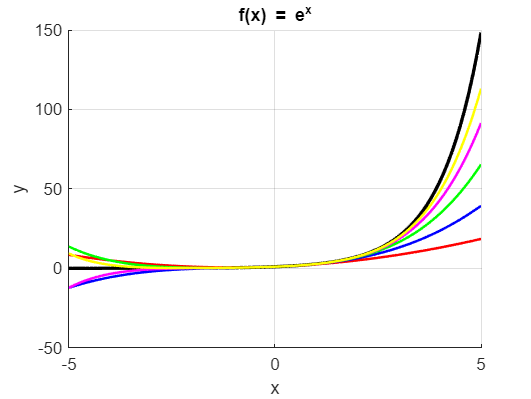


xlabel('x');
ylabel('y');
title('f(x) = e^x');
grid on;
hold off;


% b) f(x) = ln(1+x)
f = log(1+x)

$$f = \log\left(x+1\right)$$


f_numeric = matlabFunction(f);
ln_value_1 = f_numeric(1);

% functie anonima pentru a determina c_k pt oricare k
c_k = @(k) vpa(subs(diff(f, x, k), x, 0) / factorial(k));

figure;
hold on;

x_range = linspace(0, 5, 100);
plot(x_range, f_numeric(x_range), 'k', 'LineWidth', 2);

for n = min_n:max_n
    Tn = 0;
    for k = 0:n
        Tn = Tn + c_k(k) * x^k;
    end

    Tn_numeric = matlabFunction(Tn);
    
    approx_value = double(Tn_numeric(1));
    error_value = abs(ln_value_1 - approx_value);

    fprintf("T_%d(1) = %e vs f(1) = %e | Error = %e\n", n, approx_value, ln_value_1, error_value);
    plot(x_range, Tn_numeric(x_range), colors{n-1}, 'LineWidth', 1.5, 'DisplayName', sprintf('T_%d(x)', n));
end

T_2(1) = 5.000000e-01 vs f(1) = 6.931472e-01 | Error = 1.931472e-01
T_3(1) = 8.333333e-01 vs f(1) = 6.931472e-01 | Error = 1.401862e-01
T_4(1) = 5.833333e-01 vs f(1) = 6.931472e-01 | Error = 1.098138e-01
T_5(1) = 7.833333e-01 vs f(1) = 6.931472e-01 | Error = 9.018615e-02
T_6(1) = 6.166667e-01 vs f(1) = 6.931472e-01 | Error = 7.648051e-02


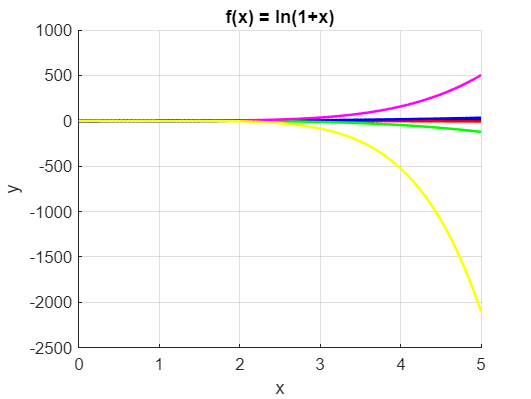


xlabel('x');
ylabel('y');
title('f(x) = ln(1+x)');
grid on;
hold off;

Aproximarea Pade


$$f(x) \approx \frac{p_m(x)}{q_k(x)} = \frac{\sum_{i=0}^{m}{a_i*x^i}}{\sum_{j=0}^{k}{b_j*x^j}} =R_{m,k}(x)$$



$$\pmatrix
{c_m & c_{m-1} & ... & c_{m-(k-2)} & c_{m-(k-1)} 
\cr 
c_{m+1} & c_{m} & ... & c_{m-(k-3)} & c_{m-(k-2)}
\cr
... & ... & ... & ... & ...
\cr
c_{m+(k-2)} & c_{m+(k-3)} & ... & c_m & c_{m-1}
\cr
c_{m+(k-1)} & c_{m+(k-2)} & ... & c_{m+1} & c_m}
*
\pmatrix{b_1 \cr b_2 \cr ... \cr b_{k-1} \cr b_k} 
=
\pmatrix{-c_{m+1} \cr -c_{m+2} \cr ... \cr -c_{m+(k-1)} \cr -c_{m+k}}$$


Unde $c_k = \frac{f^{(k)}(0)}{k!}$

syms x

% a) my_pade.m

% b)
x_range = linspace(-1, 1, 25);

R11_b = my_pade(@(x) exp(x), 1, 1, x)

$$R11\_b = -\frac{3\,x+2}{x-2}$$

R22_b = my_pade(@(x) exp(x), 2, 2, x)

$$R22\_b = \frac{11\,x^{2}+18\,x+12}{x^{2}-6\,x+12}$$


exp_points = zeros(size(x_range));
R11_b_points = zeros(size(x_range));
R22_b_points = zeros(size(x_range));

for i = 1:25
    exp_points(i) = exp(x_range(i));
    R11_b_points(i) = double(subs(R11_b, x, x_range(i)));
    R22_b_points(i) = double(subs(R22_b, x, x_range(i)));

    %fprintf("exp(%f) = %e | R11_b(%f) = %e | R22_b(%f) = %e\n", ...
    %    x_range(i), exp_points(i), x_range(i), R11_b_points(i), x_range(i), R22_b_points(i));
    
    error_R11_b = abs(exp_points(i) - R11_b_points(i));
    fprintf("exp(%f) vs Pade(1,1)(%f) = %e\n", ...
        x_range(i), x_range(i), error_R11_b);

    error_R22_b = abs(exp_points(i) - R22_b_points(i));
    fprintf("exp(%f) vs Pade(2,2)(%f) = %e\n\n", ...
        x_range(i), x_range(i), error_R22_b);
end

exp(-1.000000) vs Pade(1,1)(-1.000000) = 7.012128e-01


exp(-1.000000) vs Pade(2,2)(-1.000000) = 1.047215e-01



exp(-0.916667) vs Pade(1,1)(-0.916667) = 6.569925e-01


exp(-0.916667) vs Pade(2,2)(-0.916667) = 1.412355e-01



exp(-0.833333) vs Pade(1,1)(-0.833333) = 6.110688e-01


exp(-0.833333) vs Pade(2,2)(-0.833333) = 1.724318e-01



exp(-0.750000) vs Pade(1,1)(-0.750000) = 5.632756e-01


exp(-0.750000) vs Pade(2,2)(-0.750000) = 1.976413e-01



exp(-0.666667) vs Pade(1,1)(-0.666667) = 5.134171e-01


exp(-0.666667) vs Pade(2,2)(-0.666667) = 2.161198e-01



exp(-0.583333) vs Pade(1,1)(-0.583333) = 4.612610e-01


exp(-0.583333) vs Pade(2,2)(-0.583333) = 2.270400e-01



exp(-0.500000) vs Pade(1,1)(-0.500000) = 4.065307e-01


exp(-0.500000) vs Pade(2,2)(-0.500000) = 2.294815e-01



exp(-0.416667) vs Pade(1,1)(-0.416667) = 3.488958e-01


exp(-0.416667) vs Pade(2,2)(-0.416667) = 2.224209e-01



exp(-0.333333) vs Pade(1,1)(-0.333333) = 2.879599e-01


exp(-0.333333) vs Pade(2,2)(-0.333333) = 2.047203e-01



exp(-0.250000) vs Pade(1,1)(-0.250000) = 2.232452e-01


exp(-0.250000) vs Pade(2,2)(-0.250000) = 1.751141e-01



exp(-0.166667) vs Pade(1,1)(-0.166667) = 1.541740e-01


exp(-0.166667) vs Pade(2,2)(-0.166667) = 1.321960e-01



exp(-0.083333) vs Pade(1,1)(-0.083333) = 8.004441e-02


exp(-0.083333) vs Pade(2,2)(-0.083333) = 7.440310e-02



exp(0.000000) vs Pade(1,1)(0.000000) = 0.000000e+00


exp(0.000000) vs Pade(2,2)(0.000000) = 0.000000e+00



exp(0.083333) vs Pade(1,1)(0.083333) = 8.700899e-02


exp(0.083333) vs Pade(2,2)(0.083333) = 9.293904e-02



exp(0.166667) vs Pade(1,1)(0.166667) = 1.822760e-01


exp(0.166667) vs Pade(2,2)(0.166667) = 2.065489e-01



exp(0.250000) vs Pade(1,1)(0.250000) = 2.874032e-01


exp(0.250000) vs Pade(2,2)(0.250000) = 3.431935e-01



exp(0.333333) vs Pade(1,1)(0.333333) = 4.043876e-01


exp(0.333333) vs Pade(2,2)(0.333333) = 5.054865e-01



exp(0.416667) vs Pade(1,1)(0.416667) = 5.357348e-01


exp(0.416667) vs Pade(2,2)(0.416667) = 6.963121e-01



exp(0.500000) vs Pade(1,1)(0.500000) = 6.846121e-01


exp(0.500000) vs Pade(2,2)(0.500000) = 9.188463e-01



exp(0.583333) vs Pade(1,1)(0.583333) = 8.550570e-01


exp(0.583333) vs Pade(2,2)(0.583333) = 1.176576e+00



exp(0.666667) vs Pade(1,1)(0.666667) = 1.052266e+00


exp(0.666667) vs Pade(2,2)(0.666667) = 1.473319e+00



exp(0.750000) vs Pade(1,1)(0.750000) = 1.283000e+00


exp(0.750000) vs Pade(2,2)(0.750000) = 1.813233e+00



exp(0.833333) vs Pade(1,1)(0.833333) = 1.556167e+00


exp(0.833333) vs Pade(2,2)(0.833333) = 2.200829e+00



exp(0.916667) vs Pade(1,1)(0.916667) = 1.883675e+00


exp(0.916667) vs Pade(2,2)(0.916667) = 2.640971e+00



exp(1.000000) vs Pade(1,1)(1.000000) = 2.281718e+00


exp(1.000000) vs Pade(2,2)(1.000000) = 3.138861e+00



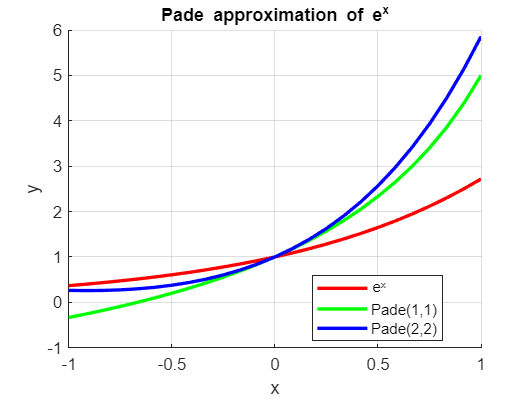


figure;
hold on;

plot(x_range, exp_points, 'r', 'LineWidth', 2, 'DisplayName', 'e^x');
plot(x_range, R11_b_points, 'g', 'LineWidth', 2, 'DisplayName', 'Pade(1,1)');
plot(x_range, R22_b_points, 'b', 'LineWidth', 2, 'DisplayName', 'Pade(2,2)');

legend('Location', 'best');
grid on;
xlabel('x');
ylabel('y');
title('Pade approximation of e^x');
hold off;


% c)
syms g(x)

g(x) = log(1 + x);

x_range = linspace(0, 2, 25);

R11_c = my_pade(@(x) g(x), 1, 1, x)

$$R11\_c = \frac{2\,x}{x+2}$$

R22_c = my_pade(@(x) g(x), 2, 2, x)

$$R22\_c = \frac{3\,\left(2\,x-3\,x^{2}\right)}{x^{2}+6\,x+6}$$


gx_points = zeros(size(x_range));
R11_c_points = zeros(size(x_range));
R22_c_points = zeros(size(x_range));

for i = 1:25
    gx_points(i) = exp(x_range(i));
    R11_c_points(i) = double(subs(R11_c, x, x_range(i)));
    R22_c_points(i) = double(subs(R22_c, x, x_range(i)));

    %fprintf("exp(%f) = %e | R11_b(%f) = %e | R22_b(%f) = %e\n", ...
    %    x_range(i), exp_points(i), x_range(i), R11_b_points(i), x_range(i), R22_b_points(i));
    
    error_R11_c = abs(gx_points(i) - R11_c_points(i));
    fprintf("g(%f) vs Pade(1,1)(%f) = %e\n", ...
        x_range(i), x_range(i), error_R11_c);

    error_R22_c = abs(gx_points(i) - R22_c_points(i));
    fprintf("g(%f) vs Pade(2,2)(%f) = %e\n\n", ...
        x_range(i), x_range(i), error_R22_c);
end

g(0.000000) vs Pade(1,1)(0.000000) = 1.000000e+00


g(0.000000) vs Pade(2,2)(0.000000) = 1.000000e+00



g(0.083333) vs Pade(1,1)(0.083333) = 1.006904e+00


g(0.083333) vs Pade(2,2)(0.083333) = 1.019668e+00



g(0.166667) vs Pade(1,1)(0.166667) = 1.027514e+00


g(0.166667) vs Pade(2,2)(0.166667) = 1.074641e+00



g(0.250000) vs Pade(1,1)(0.250000) = 1.061803e+00


g(0.250000) vs Pade(2,2)(0.250000) = 1.160058e+00



g(0.333333) vs Pade(1,1)(0.333333) = 1.109898e+00


g(0.333333) vs Pade(2,2)(0.333333) = 1.272325e+00



g(0.416667) vs Pade(1,1)(0.416667) = 1.172069e+00


g(0.416667) vs Pade(2,2)(0.416667) = 1.408810e+00



g(0.500000) vs Pade(1,1)(0.500000) = 1.248721e+00


g(0.500000) vs Pade(2,2)(0.500000) = 1.567640e+00



g(0.583333) vs Pade(1,1)(0.583333) = 1.340389e+00


g(0.583333) vs Pade(2,2)(0.583333) = 1.747542e+00



g(0.666667) vs Pade(1,1)(0.666667) = 1.447734e+00


g(0.666667) vs Pade(2,2)(0.666667) = 1.947734e+00



g(0.750000) vs Pade(1,1)(0.750000) = 1.571545e+00


g(0.750000) vs Pade(2,2)(0.750000) = 2.167847e+00



g(0.833333) vs Pade(1,1)(0.833333) = 1.712741e+00


g(0.833333) vs Pade(2,2)(0.833333) = 2.407864e+00



g(0.916667) vs Pade(1,1)(0.916667) = 1.872369e+00


g(0.916667) vs Pade(2,2)(0.916667) = 2.668076e+00



g(1.000000) vs Pade(1,1)(1.000000) = 2.051615e+00


g(1.000000) vs Pade(2,2)(1.000000) = 2.949051e+00



g(1.083333) vs Pade(1,1)(1.083333) = 2.251809e+00


g(1.083333) vs Pade(2,2)(1.083333) = 3.251617e+00



g(1.166667) vs Pade(1,1)(1.166667) = 2.474428e+00


g(1.166667) vs Pade(2,2)(1.166667) = 3.576841e+00



g(1.250000) vs Pade(1,1)(1.250000) = 2.721112e+00


g(1.250000) vs Pade(2,2)(1.250000) = 3.926028e+00



g(1.333333) vs Pade(1,1)(1.333333) = 2.993668e+00


g(1.333333) vs Pade(2,2)(1.333333) = 4.300710e+00



g(1.416667) vs Pade(1,1)(1.416667) = 3.294085e+00


g(1.416667) vs Pade(2,2)(1.416667) = 4.702655e+00



g(1.500000) vs Pade(1,1)(1.500000) = 3.624546e+00


g(1.500000) vs Pade(2,2)(1.500000) = 5.133863e+00



g(1.583333) vs Pade(1,1)(1.583333) = 3.987445e+00


g(1.583333) vs Pade(2,2)(1.583333) = 5.596581e+00



g(1.666667) vs Pade(1,1)(1.666667) = 4.385399e+00


g(1.666667) vs Pade(2,2)(1.666667) = 6.093307e+00



g(1.750000) vs Pade(1,1)(1.750000) = 4.821269e+00


g(1.750000) vs Pade(2,2)(1.750000) = 6.626807e+00



g(1.833333) vs Pade(1,1)(1.833333) = 5.298179e+00


g(1.833333) vs Pade(2,2)(1.833333) = 7.200131e+00



g(1.916667) vs Pade(1,1)(1.916667) = 5.819536e+00


g(1.916667) vs Pade(2,2)(1.916667) = 7.816626e+00



g(2.000000) vs Pade(1,1)(2.000000) = 6.389056e+00


g(2.000000) vs Pade(2,2)(2.000000) = 8.479965e+00



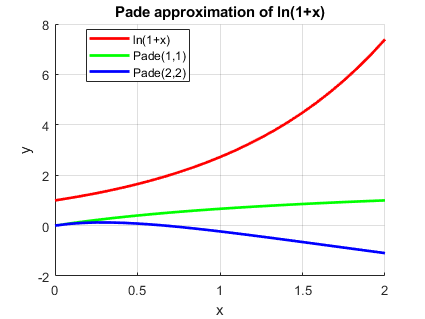


figure;
hold on;

plot(x_range, gx_points, 'r', 'LineWidth', 2, 'DisplayName', 'ln(1+x)');
plot(x_range, R11_c_points, 'g', 'LineWidth', 2, 'DisplayName', 'Pade(1,1)');
plot(x_range, R22_c_points, 'b', 'LineWidth', 2, 'DisplayName', 'Pade(2,2)');

legend('Location', 'best');
grid on;
xlabel('x');
ylabel('y');
title('Pade approximation of ln(1+x)');
hold off;


% concluzie: se comporta din ce in ce mai prost cu cat valorile lui x cresc
% solutie?: ar trebui m si k de ordin mai mare

Dezvoltari Maclaurin + aproximari Pade pentru functia $Bessel \; J_0(2x)$


$$J_n(x) = \frac{1}{\pi}*\int_{0}^{\pi}{\cos(x\sin{\theta} - n\theta)\,d\theta}$$



$$J_0(2x) = \frac{1}{\pi} * \int_{0}^{\pi}{cos(2x\sin{\theta})\,d\theta$$


[https://encyclopediaofmath.org/wiki/Bessel_functions](https://encyclopediaofmath.org/wiki/Bessel_functions)


$$J_n(x) = (\frac{x}{2})^n*\sum_{k=0}^{\infty}{\frac{(-1)^k}{k!*(n+k)!} * (\frac{x}{2})^{2k}$$



$$J_0(x) = \sum_{k=0}^{\infty}{\frac{(-1)^k}{(k!)^2}}*(\frac{x}{2})^{2k}$$



$$J_0{2x} = \sum_{k=0}^{\infty}{\frac{(-1)^k}{(k!)^2}}*x^{2k}$$


syms Jk_2x x k

Jk_2x = ((-1)^k / factorial(k)^2) * x^(2*k);
Jk_2x_5 = symsum(Jk_2x, k, 0, 5);

Tnf_9 = taylor(Jk_2x_5, x, 'order', 6);
Tnf_9_numeric = matlabFunction(Tnf_9);
disp(Tnf_9);

$$\frac{x^{4}}{4}-x^{2}+1$$

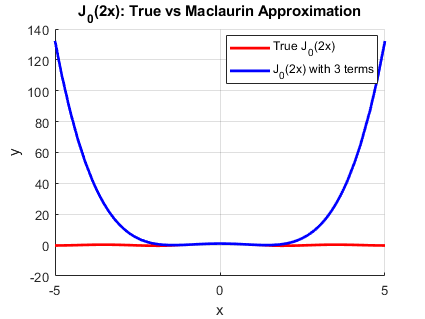


% comparing J_0(2x) with its Maclaurin series in a plot
figure;
hold on;

fplot(@(x) besselj(0, 2*x), [-5, 5], 'r', 'LineWidth', 2, 'DisplayName', 'True J_0(2x)');
fplot(Tnf_9_numeric, [-5, 5], 'b', 'LineWidth', 2, 'DisplayName', 'J_0(2x) with 3 terms');

legend('Location', 'best');
grid on;
xlabel('x');
ylabel('y');
title('J_0(2x): True vs Maclaurin Approximation');
hold off;

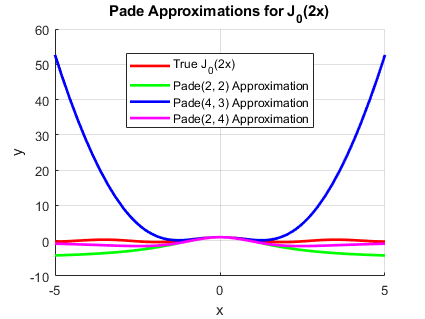


% finding Pade approximations for given m and k
R22_9 = my_pade(@(x) besselj(0, 2*x), 2, 2, x);
R43_9 = my_pade(@(x) besselj(0, 2*x), 4, 3, x);
R24_9 = my_pade(@(x) besselj(0, 2*x), 2, 4, x);

R22_9_numeric = matlabFunction(R22_9);
R43_9_numeric = matlabFunction(R43_9);
R24_9_numeric = matlabFunction(R24_9);

figure;
hold on;

fplot(@(x) besselj(0, 2*x), [-5, 5], 'r', 'LineWidth', 2, 'DisplayName', 'True J_0(2x)');
fplot(R22_9_numeric, [-5, 5], 'g', 'LineWidth', 2, 'DisplayName', 'Pade(2, 2) Approximation');
fplot(R43_9_numeric, [-5, 5], 'b', 'LineWidth', 2, 'DisplayName', 'Pade(4, 3) Approximation');
fplot(R24_9_numeric, [-5, 5], 'm', 'LineWidth', 2, 'DisplayName', 'Pade(2, 4) Approximation');

legend('Location', 'best');
grid on;
xlabel('x');
ylabel('y');
title('Pade Approximations for J_0(2x)');
hold off;


$$f(x) = \frac{e^x - 1- x}{x^2}$$


Eroare relativ mare pentru $x \approx 0$. De ce?

[https://en.wikipedia.org/wiki/Catastrophic_cancellation](https://en.wikipedia.org/wiki/Catastrophic_cancellation)

Cu cat $x$ tinde din ce in ce mai mult la 0, atat numaratorul cat si numitorul tind la 0. 

Acest efect se numeste "catastrophic cancellation". La numarator, pentru valori foarte mici ale lui x, valoarea calculata o sa fie foarte mica, aceasta valoare depinzand de precizia sistemului de calcul de a stoca floating-point values. De exemplu:


$$Pentru \; x = {1e-7} \Rightarrow e^x \approx 1.0000001$$



$$e^x - 1 \approx 0.0000001 \Rightarrow e^x - 1 -x = 0.0000001 - 0.0000001 \approx 0.0000...$$


Sistemul de calcul da rateuri cand incearca sa efectueze operatii aritmetice cu valori foarte foarte mici, iar unele limbaje dau rateuri cu precizia si pentru valori acceptabile (ex: JavaScript: 1.0 + 2.0 = 3.00000000...4???)

Pentru un calcul mai eficient, putem folosi seria Taylor a lui $e^x$.


$$f(x) = \frac{e^x - 1 -x}{x^2} = \frac{1+x+\frac{x^2}{2!}+\frac{x^3}{3!} + ... - 1 -x}{x^2}$$



$$f(x) = \frac{\frac{x^2}{2!} + \frac{x^3}{3!} + ...}{x^2} = \frac{1}{2!} + \frac{x}{3!} + \frac{x^2}{4!} + ...$$



$$f(x) = \sum_{k=1}^{\infty}{\frac{x^{k-1}}{(k+1)!}}$$


syms x

f = (exp(x) - 1 - x) / x^2;
x_range = linspace(0, 2, 100);

for i=1:100
    limit_val = limit(f, x, x_range(i));
    improved_val = improved_f_10(x_range(i));
    val_error = vpa(abs(limit_val - improved_val));

    fprintf("limit_val = %f | improved_val = %f | error = %e", limit_val, improved_val, val_error);
end

Result: 5.000000e-01

limit_val = 0.500000 | improved_val = 0.500000 | error = 0.000000e+00

Result: 5.033841e-01

limit_val = 0.503384 | improved_val = 0.503384 | error = 5.457400e-24

Result: 5.068026e-01

limit_val = 0.506803 | improved_val = 0.506803 | error = 1.966951e-23

Result: 5.102559e-01

limit_val = 0.510256 | improved_val = 0.510256 | error = 1.375009e-21

Result: 5.137446e-01

limit_val = 0.513745 | improved_val = 0.513745 | error = 2.458800e-20

Result: 5.172689e-01

limit_val = 0.517269 | improved_val = 0.517269 | error = 2.329988e-19

Result: 5.208293e-01

limit_val = 0.520829 | improved_val = 0.520829 | error = 1.442534e-18

Result: 5.244264e-01

limit_val = 0.524426 | improved_val = 0.524426 | error = 6.750505e-18

Result: 5.280605e-01

limit_val = 0.528060 | improved_val = 0.528060 | error = 2.569750e-17

Result: 5.317321e-01

limit_val = 0.531732 | improved_val = 0.531732 | error = 8.358855e-17

Result: 5.354416e-01

limit_val = 0.535442 | improved_val = 0.535442 | error = 2.401100e-16

Result: 5.391896e-01

limit_val = 0.539190 | improved_val = 0.539190 | error = 6.237587e-16

Result: 5.429765e-01

limit_val = 0.542976 | improved_val = 0.542976 | error = 1.491376e-15

Result: 5.468027e-01

limit_val = 0.546803 | improved_val = 0.546803 | error = 3.325788e-15

Result: 5.506688e-01

limit_val = 0.550669 | improved_val = 0.550669 | error = 6.989224e-15

Result: 5.545753e-01

limit_val = 0.554575 | improved_val = 0.554575 | error = 1.395562e-14

Result: 5.585227e-01

limit_val = 0.558523 | improved_val = 0.558523 | error = 2.665172e-14

Result: 5.625114e-01

limit_val = 0.562511 | improved_val = 0.562511 | error = 4.894462e-14

Result: 5.665420e-01

limit_val = 0.566542 | improved_val = 0.566542 | error = 8.682241e-14

Result: 5.706150e-01

limit_val = 0.570615 | improved_val = 0.570615 | error = 1.493257e-13

Result: 5.747310e-01

limit_val = 0.574731 | improved_val = 0.574731 | error = 2.497995e-13

Result: 5.788905e-01

limit_val = 0.578890 | improved_val = 0.578890 | error = 4.075475e-13

Result: 5.830940e-01

limit_val = 0.583094 | improved_val = 0.583094 | error = 6.499901e-13

Result: 5.873420e-01

limit_val = 0.587342 | improved_val = 0.587342 | error = 1.015439e-12

Result: 5.916352e-01

limit_val = 0.591635 | improved_val = 0.591635 | error = 1.556627e-12

Result: 5.959741e-01

limit_val = 0.595974 | improved_val = 0.595974 | error = 2.345146e-12

Result: 6.003593e-01

limit_val = 0.600359 | improved_val = 0.600359 | error = 3.476976e-12

Result: 6.047914e-01

limit_val = 0.604791 | improved_val = 0.604791 | error = 5.079317e-12

Result: 6.092709e-01

limit_val = 0.609271 | improved_val = 0.609271 | error = 7.318944e-12

Result: 6.137984e-01

limit_val = 0.613798 | improved_val = 0.613798 | error = 1.041237e-11

Result: 6.183747e-01

limit_val = 0.618375 | improved_val = 0.618375 | error = 1.463809e-11

Result: 6.230002e-01

limit_val = 0.623000 | improved_val = 0.623000 | error = 2.035130e-11

Result: 6.276756e-01

limit_val = 0.627676 | improved_val = 0.627676 | error = 2.800136e-11

Result: 6.324016e-01

limit_val = 0.632402 | improved_val = 0.632402 | error = 3.815259e-11

Result: 6.371787e-01

limit_val = 0.637179 | improved_val = 0.637179 | error = 5.150863e-11

Result: 6.420077e-01

limit_val = 0.642008 | improved_val = 0.642008 | error = 6.894113e-11

Result: 6.468892e-01

limit_val = 0.646889 | improved_val = 0.646889 | error = 9.152319e-11

Result: 6.518239e-01

limit_val = 0.651824 | improved_val = 0.651824 | error = 1.205681e-10

Result: 6.568124e-01

limit_val = 0.656812 | improved_val = 0.656812 | error = 1.576744e-10

Result: 6.618554e-01

limit_val = 0.661855 | improved_val = 0.661855 | error = 2.047776e-10

Result: 6.669537e-01

limit_val = 0.666954 | improved_val = 0.666954 | error = 2.642095e-10

Result: 6.721079e-01

limit_val = 0.672108 | improved_val = 0.672108 | error = 3.387662e-10

Result: 6.773188e-01

limit_val = 0.677319 | improved_val = 0.677319 | error = 4.317859e-10

Result: 6.825871e-01

limit_val = 0.682587 | improved_val = 0.682587 | error = 5.472366e-10

Result: 6.879135e-01

limit_val = 0.687913 | improved_val = 0.687913 | error = 6.898162e-10

Result: 6.932988e-01

limit_val = 0.693299 | improved_val = 0.693299 | error = 8.650651e-10

Result: 6.987437e-01

limit_val = 0.698744 | improved_val = 0.698744 | error = 1.079493e-09

Result: 7.042490e-01

limit_val = 0.704249 | improved_val = 0.704249 | error = 1.340724e-09

Result: 7.098156e-01

limit_val = 0.709816 | improved_val = 0.709816 | error = 1.657651e-09

Result: 7.154441e-01

limit_val = 0.715444 | improved_val = 0.715444 | error = 2.040622e-09

|x| >= 1. Computing function normally...
Result: 7.211354e-01

limit_val = 0.721135 | improved_val = 0.721135 | error = 1.106998e-16

|x| >= 1. Computing function normally...
Result: 7.268903e-01

limit_val = 0.726890 | improved_val = 0.726890 | error = 2.106071e-16

|x| >= 1. Computing function normally...
Result: 7.327096e-01

limit_val = 0.732710 | improved_val = 0.732710 | error = 1.247360e-16

|x| >= 1. Computing function normally...
Result: 7.385943e-01

limit_val = 0.738594 | improved_val = 0.738594 | error = 2.507626e-16

|x| >= 1. Computing function normally...
Result: 7.445450e-01

limit_val = 0.744545 | improved_val = 0.744545 | error = 3.573844e-17

|x| >= 1. Computing function normally...
Result: 7.505627e-01

limit_val = 0.750563 | improved_val = 0.750563 | error = 1.001931e-17

|x| >= 1. Computing function normally...
Result: 7.566483e-01

limit_val = 0.756648 | improved_val = 0.756648 | error = 1.211135e-16

|x| >= 1. Computing function normally...
Result: 7.628027e-01

limit_val = 0.762803 | improved_val = 0.762803 | error = 1.215590e-17

|x| >= 1. Computing function normally...
Result: 7.690266e-01

limit_val = 0.769027 | improved_val = 0.769027 | error = 1.132144e-16

|x| >= 1. Computing function normally...
Result: 7.753212e-01

limit_val = 0.775321 | improved_val = 0.775321 | error = 1.998154e-16

|x| >= 1. Computing function normally...
Result: 7.816872e-01

limit_val = 0.781687 | improved_val = 0.781687 | error = 1.493160e-16

|x| >= 1. Computing function normally...
Result: 7.881257e-01

limit_val = 0.788126 | improved_val = 0.788126 | error = 1.660952e-16

|x| >= 1. Computing function normally...
Result: 7.946375e-01

limit_val = 0.794638 | improved_val = 0.794638 | error = 1.341705e-16

|x| >= 1. Computing function normally...
Result: 8.012237e-01

limit_val = 0.801224 | improved_val = 0.801224 | error = 2.075929e-17

|x| >= 1. Computing function normally...
Result: 8.078852e-01

limit_val = 0.807885 | improved_val = 0.807885 | error = 4.272528e-17

|x| >= 1. Computing function normally...
Result: 8.146230e-01

limit_val = 0.814623 | improved_val = 0.814623 | error = 1.037905e-16

|x| >= 1. Computing function normally...
Result: 8.214382e-01

limit_val = 0.821438 | improved_val = 0.821438 | error = 1.084345e-16

|x| >= 1. Computing function normally...
Result: 8.283317e-01

limit_val = 0.828332 | improved_val = 0.828332 | error = 1.361500e-16

|x| >= 1. Computing function normally...
Result: 8.353046e-01

limit_val = 0.835305 | improved_val = 0.835305 | error = 7.081668e-19

|x| >= 1. Computing function normally...
Result: 8.423579e-01

limit_val = 0.842358 | improved_val = 0.842358 | error = 1.749491e-16

|x| >= 1. Computing function normally...
Result: 8.494928e-01

limit_val = 0.849493 | improved_val = 0.849493 | error = 3.371702e-18

|x| >= 1. Computing function normally...
Result: 8.567102e-01

limit_val = 0.856710 | improved_val = 0.856710 | error = 6.137470e-17

|x| >= 1. Computing function normally...
Result: 8.640114e-01

limit_val = 0.864011 | improved_val = 0.864011 | error = 7.022412e-17

|x| >= 1. Computing function normally...
Result: 8.713973e-01

limit_val = 0.871397 | improved_val = 0.871397 | error = 3.365100e-17

|x| >= 1. Computing function normally...
Result: 8.788692e-01

limit_val = 0.878869 | improved_val = 0.878869 | error = 1.874359e-16

|x| >= 1. Computing function normally...
Result: 8.864281e-01

limit_val = 0.886428 | improved_val = 0.886428 | error = 1.940673e-16

|x| >= 1. Computing function normally...
Result: 8.940753e-01

limit_val = 0.894075 | improved_val = 0.894075 | error = 4.953298e-17

|x| >= 1. Computing function normally...
Result: 9.018120e-01

limit_val = 0.901812 | improved_val = 0.901812 | error = 8.700233e-17

|x| >= 1. Computing function normally...
Result: 9.096392e-01

limit_val = 0.909639 | improved_val = 0.909639 | error = 8.841282e-17

|x| >= 1. Computing function normally...
Result: 9.175583e-01

limit_val = 0.917558 | improved_val = 0.917558 | error = 2.219540e-16

|x| >= 1. Computing function normally...
Result: 9.255705e-01

limit_val = 0.925571 | improved_val = 0.925571 | error = 9.649250e-17

|x| >= 1. Computing function normally...
Result: 9.336770e-01

limit_val = 0.933677 | improved_val = 0.933677 | error = 1.218383e-16

|x| >= 1. Computing function normally...
Result: 9.418791e-01

limit_val = 0.941879 | improved_val = 0.941879 | error = 6.148768e-17

|x| >= 1. Computing function normally...
Result: 9.501781e-01

limit_val = 0.950178 | improved_val = 0.950178 | error = 1.064308e-16

|x| >= 1. Computing function normally...
Result: 9.585753e-01

limit_val = 0.958575 | improved_val = 0.958575 | error = 1.369383e-16

|x| >= 1. Computing function normally...
Result: 9.670719e-01

limit_val = 0.967072 | improved_val = 0.967072 | error = 3.938899e-17

|x| >= 1. Computing function normally...
Result: 9.756695e-01

limit_val = 0.975669 | improved_val = 0.975669 | error = 8.374308e-18

|x| >= 1. Computing function normally...
Result: 9.843692e-01

limit_val = 0.984369 | improved_val = 0.984369 | error = 2.302963e-16

|x| >= 1. Computing function normally...
Result: 9.931726e-01

limit_val = 0.993173 | improved_val = 0.993173 | error = 1.140013e-16

|x| >= 1. Computing function normally...
Result: 1.002081e+00

limit_val = 1.002081 | improved_val = 1.002081 | error = 2.822096e-18

|x| >= 1. Computing function normally...
Result: 1.011096e+00

limit_val = 1.011096 | improved_val = 1.011096 | error = 2.680718e-16

|x| >= 1. Computing function normally...
Result: 1.020218e+00

limit_val = 1.020218 | improved_val = 1.020218 | error = 1.035828e-17

|x| >= 1. Computing function normally...
Result: 1.029450e+00

limit_val = 1.029450 | improved_val = 1.029450 | error = 7.364765e-17

|x| >= 1. Computing function normally...
Result: 1.038793e+00

limit_val = 1.038793 | improved_val = 1.038793 | error = 1.015681e-16

|x| >= 1. Computing function normally...
Result: 1.048248e+00

limit_val = 1.048248 | improved_val = 1.048248 | error = 1.069351e-16

|x| >= 1. Computing function normally...
Result: 1.057818e+00

limit_val = 1.057818 | improved_val = 1.057818 | error = 1.228784e-16

|x| >= 1. Computing function normally...
Result: 1.067502e+00

limit_val = 1.067502 | improved_val = 1.067502 | error = 1.190417e-16

|x| >= 1. Computing function normally...
Result: 1.077304e+00

limit_val = 1.077304 | improved_val = 1.077304 | error = 5.818192e-17

|x| >= 1. Computing function normally...
Result: 1.087224e+00

limit_val = 1.087224 | improved_val = 1.087224 | error = 8.763149e-17

|x| >= 1. Computing function normally...
Result: 1.097264e+00

limit_val = 1.097264 | improved_val = 1.097264 | error = 4.492785e-17